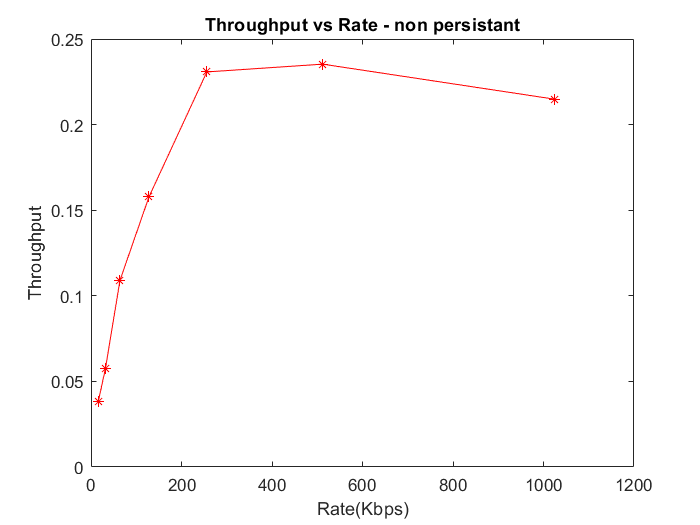

 close all
 clc
 PacketSize = [68,136,272,544,1088,2176,4352];
 Rate = PacketSize/(0.034*(1000/8));
 
%% non persistent
 Throughput_non = [0.0381335,0.0576196,0.109025,0.157732,0.230766,0.23531,0.214871];
 Delayendtoend_non = [0.051929,0.0516885,0.062512,0.0743063,0.0972645,0.186945,0.327046];
 
 figure
 plot(Rate,Throughput_non,'r*-')
 title("Throughput vs Rate - non persistant")
 xlabel('Rate(Kbps)')
 ylabel('Throughput')

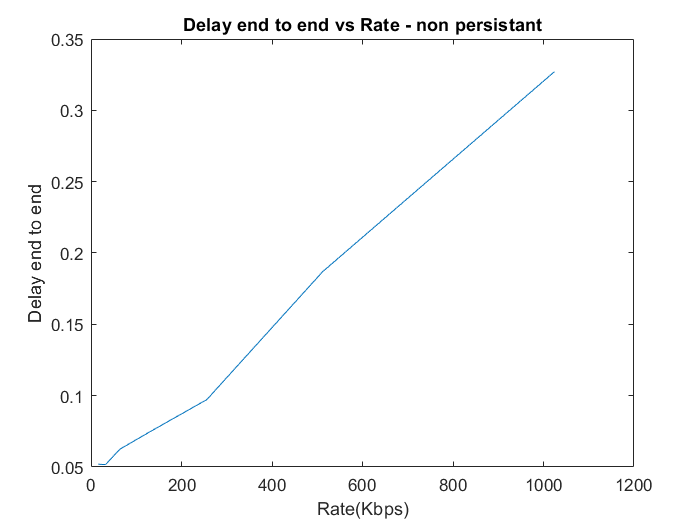

 figure
 plot(Rate,Delayendtoend_non)
 title("Delay end to end vs Rate - non persistant")
 xlabel('Rate(Kbps)')
 ylabel('Delay end to end')

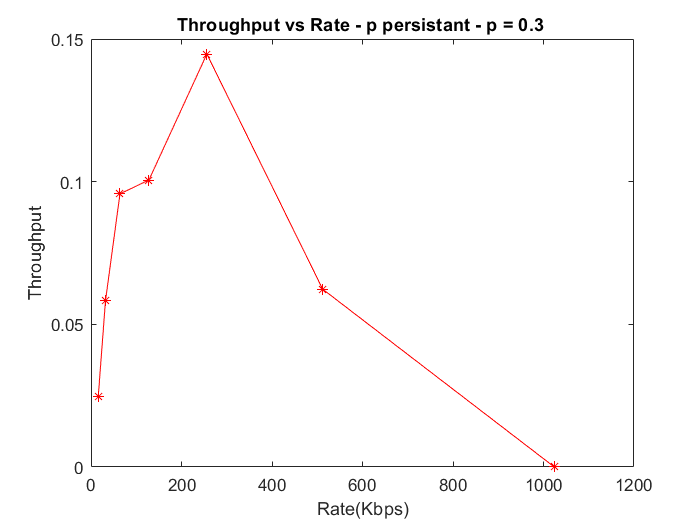

 
 %% P persistent p=0.3
 Throughput_p_03 = [0.0246034,0.0582364,0.0957398,0.100578,0.144737,0.062321,0.0];
 Delayendtoend_p_03 = [0.265618,1.52135,1.5236,1.52923,1.53773,300,600]; %% too much
 figure
 plot(Rate,Throughput_p_03,'r*-')
 title("Throughput vs Rate - p persistant - p = 0.3 ")
 xlabel('Rate(Kbps)')
 ylabel('Throughput')

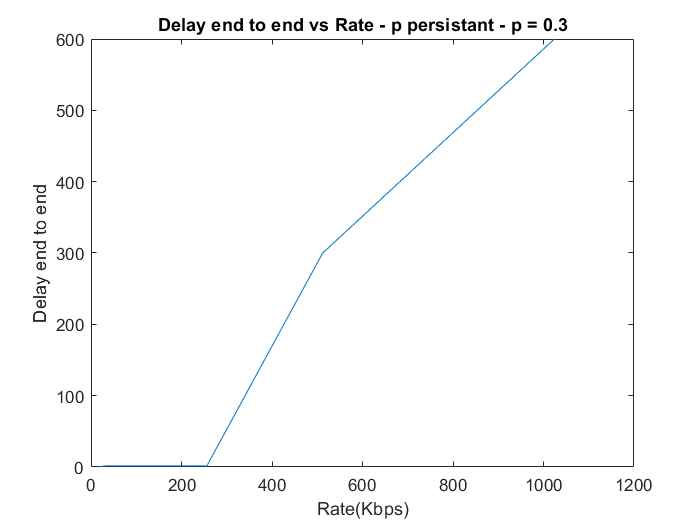

 figure
 plot(Rate,Delayendtoend_p_03)
 title("Delay end to end vs Rate - p persistant - p = 0.3")
 xlabel('Rate(Kbps)')
 ylabel('Delay end to end')

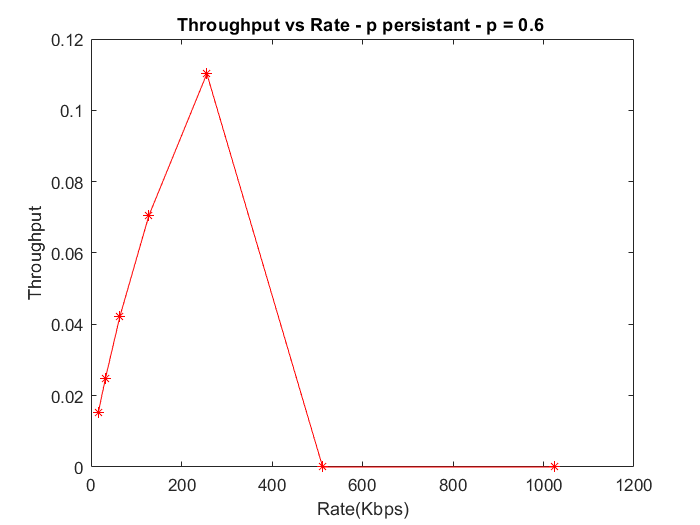

 %% P persistent p=0.6
 Throughput_p_06 = [0.0151691,0.0249081,0.0422883,0.0705349,0.110255,0,0];
 Delayendtoend_p_06 = [0.267604,0.268401,0.269995,0.273184,0.279558,150,300];
 figure
 plot(Rate,Throughput_p_06,'r*-')
 title("Throughput vs Rate - p persistant - p = 0.6 ")
 xlabel('Rate(Kbps)')
 ylabel('Throughput')

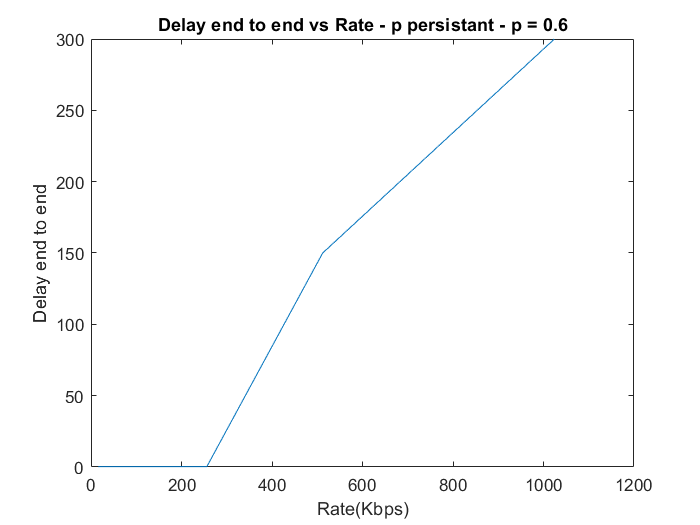

 figure
 plot(Rate,Delayendtoend_p_06)
 title("Delay end to end vs Rate - p persistant - p = 0.6")
 xlabel('Rate(Kbps)')
 ylabel('Delay end to end')

 
 %% ALOHA
 Throughput_aloha =0.5*[0.0381335,0.0576196,0.109025,0.157732,0.170766,0,0]

Throughput_aloha =     0.0191    0.0288    0.0545    0.0789    0.0854         0         0


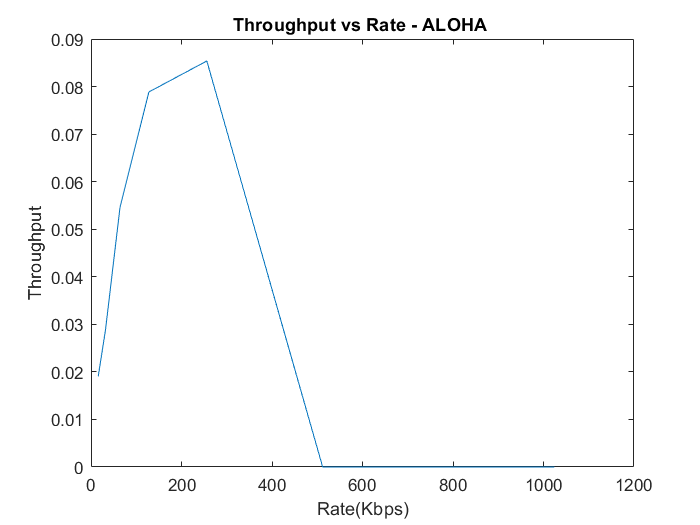

 Delayendtoend_aloha = [0.051929,0.0516885,0.062512,0.0743063,0.0972645,0.186945,0.327046 ];
 figure
 plot(Rate,Throughput_aloha)
 title("Throughput vs Rate - ALOHA ")
 xlabel('Rate(Kbps)')
 ylabel('Throughput')

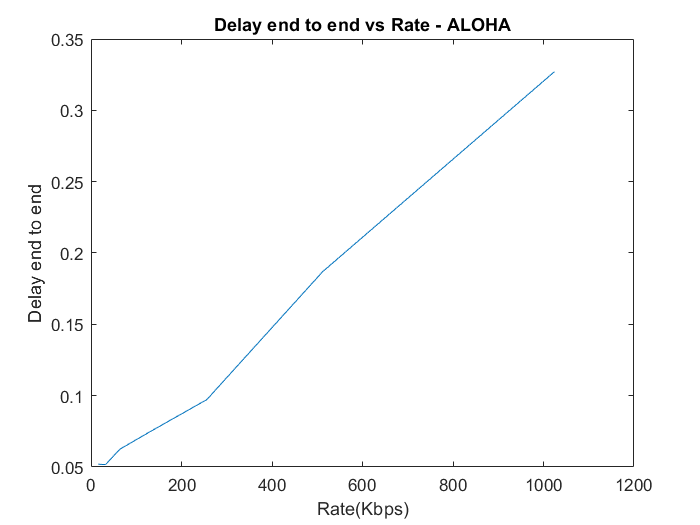

 figure
 plot(Rate,Delayendtoend_aloha)
 title("Delay end to end vs Rate - ALOHA")
 xlabel('Rate(Kbps)')
 ylabel('Delay end to end')

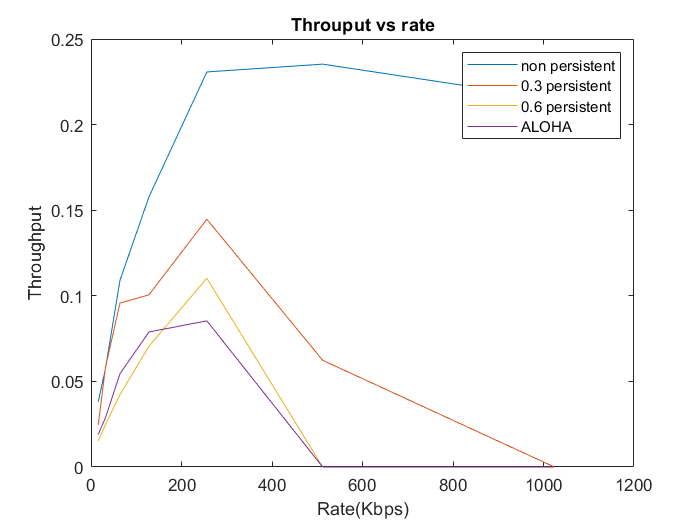

 %% altogether throughput
 figure 
 plot(Rate,Throughput_non);
 hold on  
 plot(Rate,Throughput_p_03);
 hold on
 plot(Rate,Throughput_p_06);
 hold on
 plot(Rate,Throughput_aloha);
 title('Throuput vs rate');
 xlabel('Rate(Kbps)');
 ylabel('Throughput');
 legend('non persistent','0.3 persistent','0.6 persistent','ALOHA')

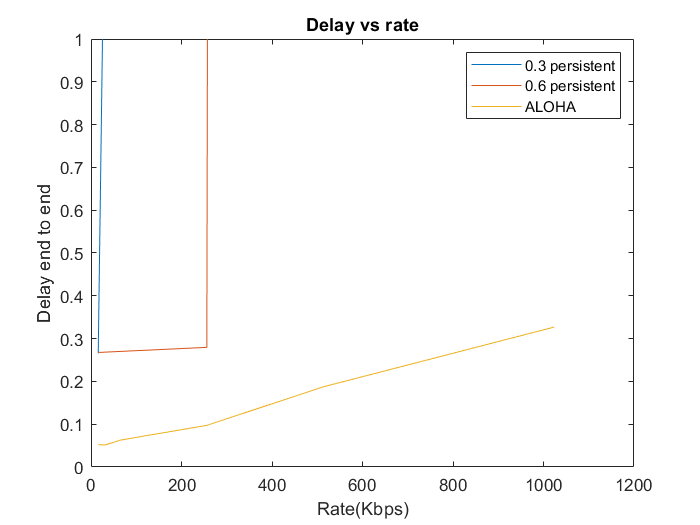

  %% altogether delay
 figure 
 %plot(Rate,Delayendtoend_non);
 %hold on  
 plot(Rate,Delayendtoend_p_03);
 hold on
 plot(Rate,Delayendtoend_p_06);
 hold on
 plot(Rate,Delayendtoend_aloha);
 title('Delay vs rate');
 xlabel('Rate(Kbps)');
 ylabel('Delay end to end');
 legend('0.3 persistent','0.6 persistent','ALOHA')
 ylim([0 1])